# Coupled Oscillators

## Initialization

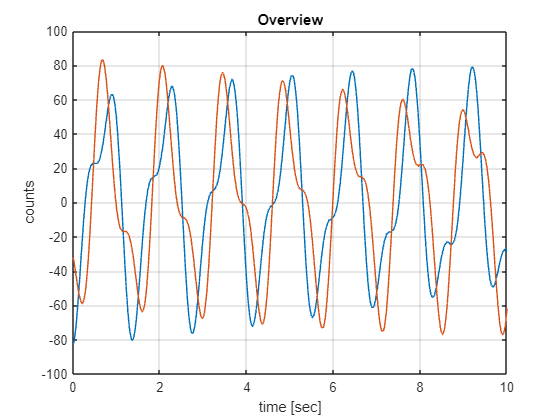

clear
close all
clc

%
file_to_load = "C:\Users\Olga\Trainig\CoupledOscillator231107\c_5.txt";

import_co

time = times2;
x1 = countA1;
x2 = countB1;

x1 = x1 - mean(x1);
x2 = x2 - mean(x2);

%
hf1 = figure;
hax = axes;
plot(hax, time, x1,  time, x2)
grid on
hold on
xlabel('time [sec]')
ylabel('counts')
title('Overview')

## Data

As measured in the lab

mass_c1 = 208.9; %[gr] mass of the cart 1
mass_c2 = 208.8; %[gr] mass of the cart 2
mass_k1 = 17.0; %[gr] mass of spring 1
mass_k2 = 11.7; %[gr] mass of spring 2
mass_k3 = 17.0; %[gr] mass of spring 2
mass_tot1 = mass_c1 + mass_k1/2 +  mass_k2/2;
mass_tot2 = mass_c2 + mass_k2/2 +  mass_k3/2;

dL = 97.95; %[mm] length difference for spring stiffness calculation
dm_k1 = 44.8; %[gr] delta force for spring 1
dm_k2 = 68.6; %[gr] delta force for spring 2
dm_k3 = 44.8; %[gr] delta force for spring 2

num_count = 236; % num of counts on the carriage
leng_c = 123; %[mm] length of carriage

g = 9.81e3; % [mm/sec^2]

## Springs' stiffness

Calculation from above data

k1 = dm_k1*g/dL; %[gr/sec^2]
k2 = dm_k2*g/dL; %[gr/sec^2]
k3 = dm_k3*g/dL; %[gr/sec^2]
k_tot = k1 + k2 + k3; %[gr/sec^2] ?

## Natural Frequencies

For 2 deg. of freedom system

M1 = [ mass_c1 0 ; 0 mass_c2]; %[g]
K1 = [k1+k2 -k2 ; -k2 k2+k3]; %[gr/sec^2]

A = K1*inv(M1);
[eigvec,eigval] = eig(A);

freqs_theory = sqrt(eigval)/2/pi;

## Transform into generalizes coordinates

And plot all displacements

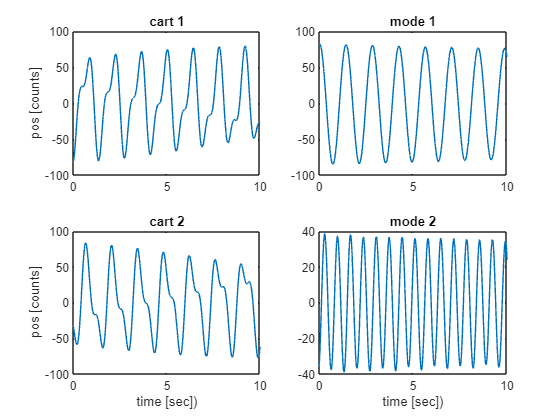

xvec = [x1 x2];

qvec = xvec * eigvec ; 

q1 = qvec(:,1);
q2 = qvec(:,2);

figure
ax1 = subplot(2,2,1);
plot(time,x1)
title('cart 1')
ylabel('pos [counts]')
hold on
ax2 = subplot(2,2,3);
plot(time,x2)
title('cart 2')
ylabel('pos [counts]')
xlabel('time [sec])')
hold on
ax3 = subplot(2,2,2);
plot(time,q1)
title('mode 1')
hold on
ax4 = subplot(2,2,4);
plot(time,q2)
title('mode 2')
xlabel('time [sec])')
hold on

## Get modal frequencies from measurments

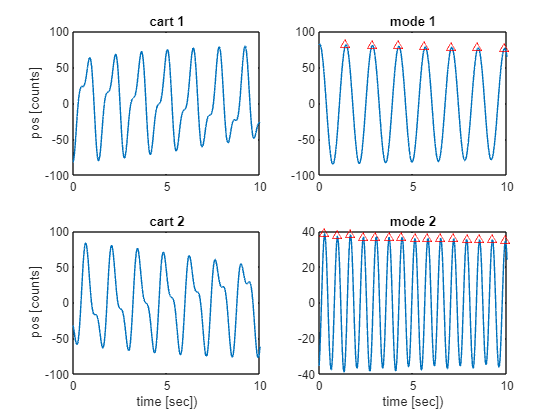

[pks1,locs1] = findpeaks(q1,'MinPeakDistance',20,'MinPeakProminence',10);
[pks2,locs2] = findpeaks(q2,'MinPeakDistance',20,'MinPeakProminence',10);

plot(ax3, time(locs1), pks1, '^r')
plot(ax4, time(locs2), pks2, '^r')


freq1 = (length(locs1) - 1) / (time(locs1(end)) - time(locs1(1))); %[Hz]
omega1 = 2*pi*freq1; %[rad]
freq2 = (length(locs2) - 1) / (time(locs2(end)) - time(locs2(1))); %[Hz]
omega2 = 2*pi*freq2; %[rad]

### Compare to theory

s1 = sprintf('Theoretical frequencies [Hz]: %3.2f , %3.2f\n', freqs_theory(1,1),freqs_theory(2,2));
s2 = sprintf('Experimental frequencies [Hz]: %3.2f , %3.2f', freq1,freq2);
s3 = [s1 s2];
disp(s3)

Theoretical frequencies [Hz]: 0.74 , 1.49
Experimental frequencies [Hz]: 0.71 , 1.46


## FFT

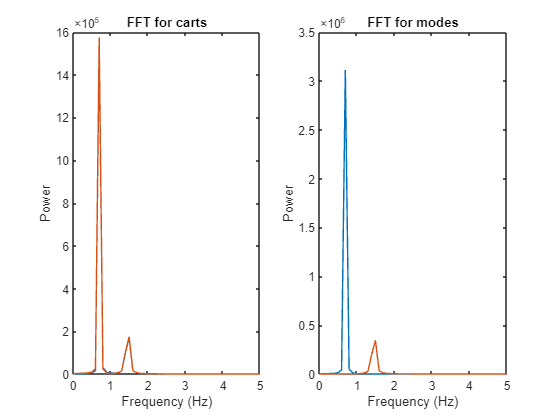

fs = 200; %sampling frequency

figure
ax = subplot(1,2,1);
fft_plot(x1,fs,ax)
fft_plot(x2,fs,ax)
xlim([0 5])
title('FFT for carts')
ax = subplot(1,2,2);
fft_plot(q1,fs,ax)
fft_plot(q2,fs,ax)
title('FFT for modes')
xlim([0 5])